### Introduction to Environmental Data Analysis and Statistical Learning 

### Exercise 4 - Probabilities

load ue_04_probability_data
whos

  Name                              Size             Bytes  Class       Attributes

  DateTime                      38849x1             310793  datetime              
  Q_USL_nogaps                  38849x1             310792  double                
  TETA_S_D_VWC_10_A_nogaps      38849x1             310792  double                



Q_USL = Q_USL_nogaps;
S_D = TETA_S_D_VWC_10_A_nogaps;
t = DateTime;

Scatter Plot

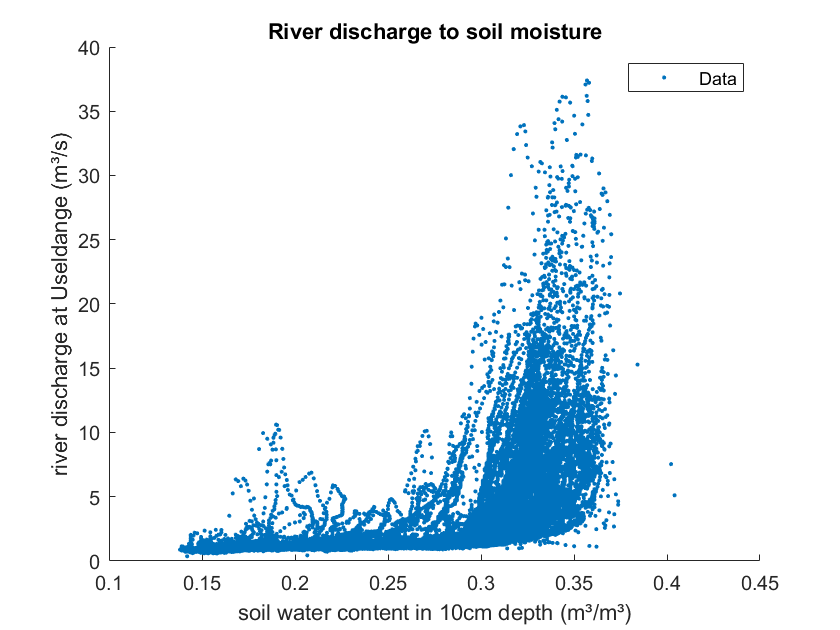

scatter(S_D, Q_USL,".")
legend("Data")
title("River discharge to soil moisture")
xlabel("soil water content in 10cm depth (m³/m³)")
ylabel("river discharge at Useldange (m³/s)")

Unconditional Probability

%probability of observing Q_USL > 15 m³/s
LargeQ = length(find(Q_USL > 15))/length(Q_USL)

LargeQ = 0.0219


%probability of observing TETA_S_D_VWC_10_A > 0.3 m³/m³
Moist = length(find(S_D > 0.3))/length(S_D)

Moist = 0.5270

%the joint probability of observing Q_USL > 15 m³/s AND TETA_S_D_VWC_10_A > 0.3 m³/m³
Pjoint = length(find(Q_USL > 15 & S_D > 0.3))/length(S_D)

Pjoint = 0.0217

%union
Punion = 1 - length(find(Q_USL < 15 & S_D < 0.3))/length(S_D)

Punion = 0.5272

Conditional Probability

%conditional probability of observing TETA_S_D_VWC_10_A > 0.3 m³/m³ for all cases where Q_USL > 15 m³/s
Pq_c = Pjoint/Moist

Pq_c = 0.0412

Psd_c = Pjoint/LargeQ

Psd_c = 0.9918

Comparasion:

The conditional probability that conditional probability of observing TETA_S_D_VWC_10_A > 0.3 m³/m³ for all cases where Q_USL > 15 m³/s is close to 1, while the conditional probability of observing Q_USL > 15 m³/s for all cases where TETA_S_D_VWC_10_A > 0.3 m³/m³ is as small as 0.04. Which mean, if we know the discharge is very high, we are quite sure that the soil water content will be high, but high soil content does not implies the discharge is high. Hence, the prediction of soil retention potential with high river discharge is much more accurate than to predict flood risk with soil moisture. We have more confidence with the former prediction.